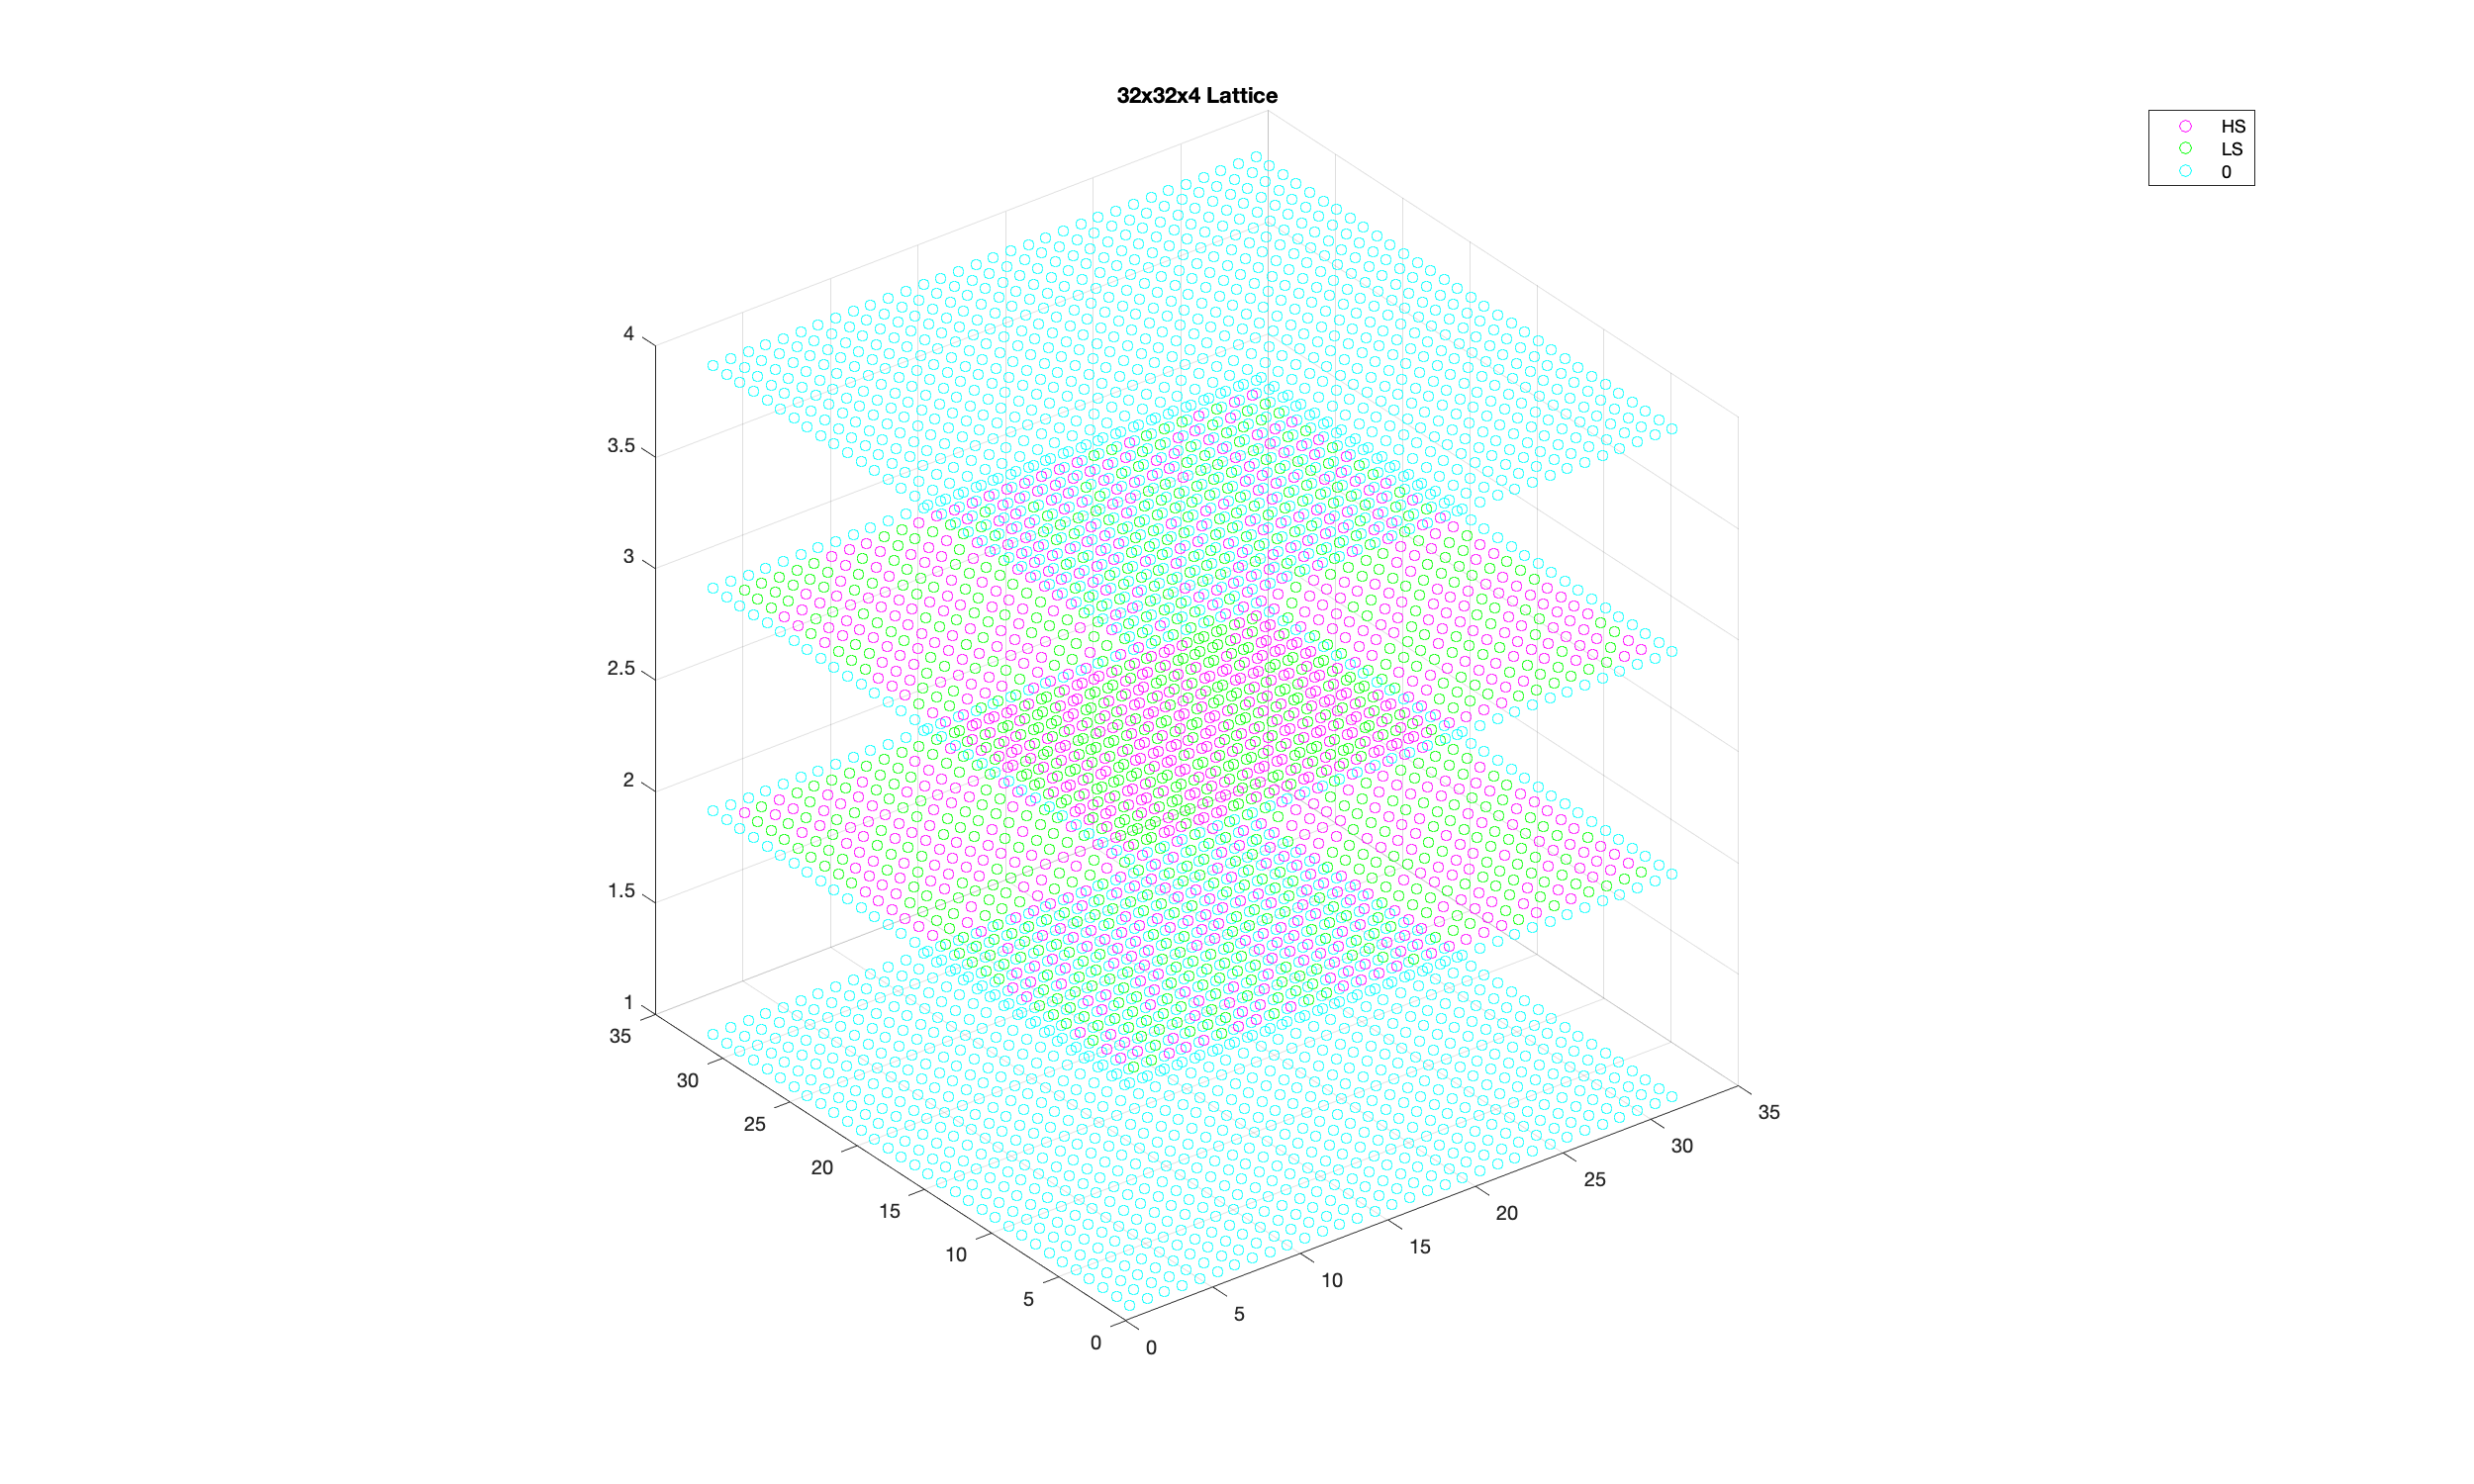

clear

N = 32;

J = 1; %eV

k_b = 8.617333262*10^-5;%eV/K

T = [100000:-1000:-100000];

beta = J./(k_b.*T);

T_c = 2.27;

steps = 3000;

%[spins, ~] = initializeLattice3D(N, N, 0, 0, 0);
% define lattice
A = zeros(N);
B = initializeLattice(N, 0, 0, 0);
C = initializeLattice(N, 0, 0, 0);

spins = cat(3, A, B, C, A);


figure;
spinVis(spins)
axis square

for n = 1:length(beta)
    for t = 1:steps
        
        for i = 2:(N-2)
            for j = 2:(N-2)
                for k = 2:3
                    
                    delta_spin = -1*spins(i, j, k) - spins(i, j, k);
                    
                    Snn = sumNN3D(spins, i, j, k);
                    
                    spins(i, j, k) = -1*spins(i, j, k);
                    
                    dE = delta_spin*(-1*J*Snn);
                    p = exp(-1*dE*beta(n));
                    r = rand;
                    
                    if dE < 0 || p >= r
                        continue
                    else
                        spins(i, j, k) = -1*spins(i, j, k);
                    end
                    
                end
            end
        end
        nHS_temp(n, t) = n_HSfrac3D(spins);
        M_temp(n, t) = abs(sum(spins, 'all'))/(2*((N-2)^2));
    end
    nHS(n) = mean(nHS_temp(n, :));
    M(n) = mean(M_temp(n, :));
end


spinVis(spins)
axis square


figure;
plot(1./(T_c.*beta), nHS, '*-')
title("High Spin Fraction vs Temperature")
xlabel("T / T_c", "Interpreter","tex")
ylabel("nHS")


figure;
plot(1./(T_c.*beta), M, '*-')
title("Magnetism vs Temperature")
xlabel("T / T_c", "Interpreter","tex")
ylabel("Magnetism")


figure;
imagesc([1:steps], 1./(T_c.*beta), nHS_temp)
xlabel("Time Step")
ylabel("T / T_c", "Interpreter","tex")
title("Molar High Fraction Per Time Step vs Temperature")
c = colorbar;
c.Label.String = 'nHS';

figure;
imagesc([1:steps], 1./(T_c.*beta), M_temp)
xlabel("Time Step")
ylabel("T / T_c", "Interpreter","tex")
title("Net Magnetism Per Time Step vs Temperature")
c = colorbar;
c.Label.String = 'Net Magnetism';